## Introduction to battery modelling with BATTMO - part 2

Electrochemical system: Thermodynamics, Kinetics,Transport

DFN model parts:

Model equations for transport in porous electrode -Fick's law, electron transport-ohm's law, charge transport at interface:butler volmer eqn, mass transport in electrolyte:concentrated solution theory.

Overpotential figure:

vary the parameters for thermodynamics at slow C rate c/20: maximum Li ion concentration,active materials

vary the transport parameters at high c rate: Diffusion coeffiecient,particle radius of electrode materials

vary the kinetic parameters-rate constant,exchange current density,activation energy,charge transfer coefficients

check_json=parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
disp(check_json.Electrolyte.initialConcentration.value)

     1



**C rate **

Solving timestep 01/45:          -> 30 Seconds, 937 Milliseconds
Solving timestep 02/45: 30 Seconds, 937 Milliseconds -> 61 Seconds, 875 Milliseconds
Solving timestep 03/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 04/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 05/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 06/45: 495 Seconds -> 990 Seconds
Solving timestep 07/45: 990 Seconds -> 1980 Seconds
Solving timestep 08/45: 1980 Seconds -> 2970 Seconds
Solving timestep 09/45: 2970 Seconds -> 1 Hour, 360 Seconds
Solving timestep 10/45: 1 Hour, 360 Seconds -> 1 Hour, 1350 Seconds
Solving timestep 11/45: 1 Hour, 1350 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 12/45: 1 Hour, 2340 Seconds -> 1 Hour, 3330 Seconds
Solving timestep 13/45: 1 Hour, 3330 Seconds -> 2 Hours, 720 Seconds
Solving timestep 14/45: 2 Hours, 720 Seconds -> 2 Hours, 1710 Seconds
Solving timestep 15/45: 2 Hours, 1710 Seconds -

*** Simulation complete. Solved 45 control steps in 2 Seconds, 578 Milliseconds ***


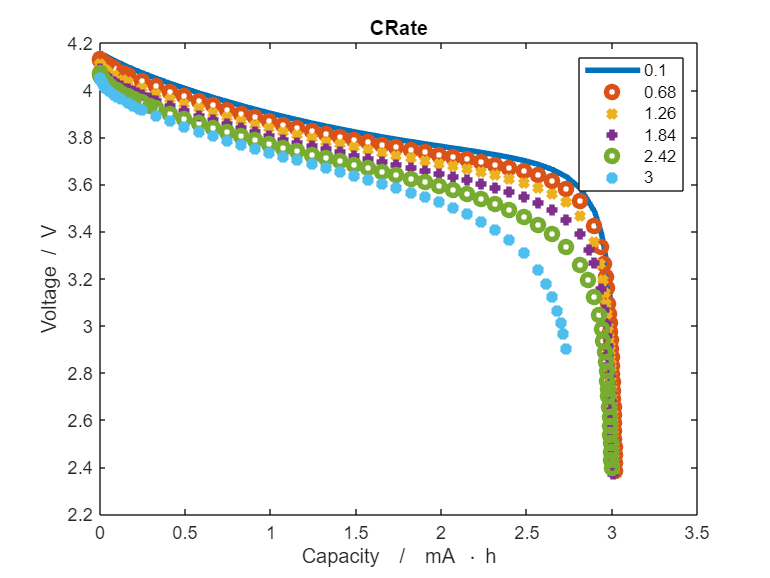

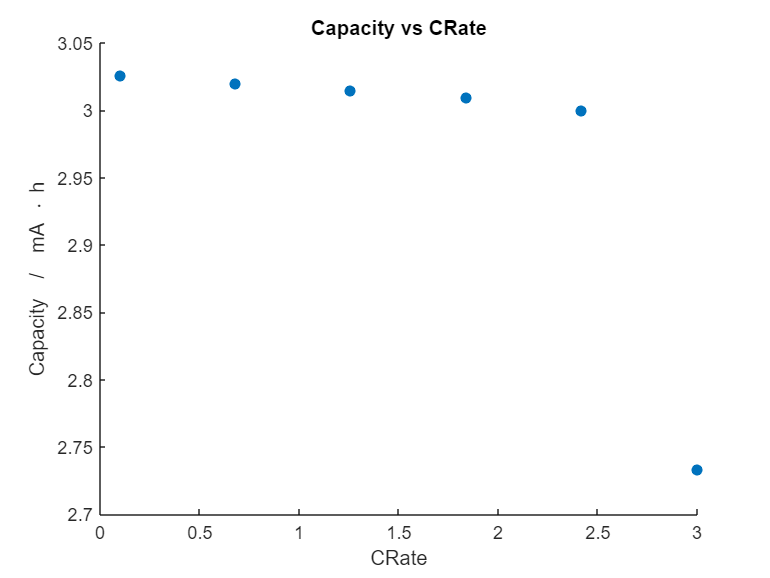

crate_array=[linspace(0.1,3,6)];
crate="Control.CRate";
plot_capacities(crate_array,crate)

#### Thermodynamic parameters

volume fraction of active material and binder in electrode

therm_mass_frac_ele_vals=[0.54,0.74,0.94];
therm_mass_frac_binder_vals=[0.43,0.23,0.03];
markers={'-',"o","x"};
output = cell(size(therm_mass_frac_ele_vals));
jsonstruct_default = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
cccv_control_protocol = parseBattmoJson('cccv_control_charge.json');%loads the CCCV protocol
jsonstruct_modified = mergeJsonStructs({cccv_control_protocol, jsonstruct_default});

parameter Control.controlPolicy is assigned twice with different values. we use the value from first jsonstruct.
parameter Control.lowerCutoffVoltage is assigned twice with different values. we use the value from first jsonstruct.
parameter SOC is assigned twice with different values. we use the value from first jsonstruct.


% instantiate an empty figure
figure()
% use a for-loop to iterate through the vector of volume fraction of active materials
for i = 1:numel(therm_mass_frac_ele_vals)
        jsonstruct_modified.Control.CRate=0.1;
        jsonstruct_modified.TimeStepping.totalTime = (1./jsonstruct_modified.Control.CRate) .* 3600 .* 1.2;
        jsonstruct_modified.NegativeElectrode.Coating.ActiveMaterial.massFraction=therm_mass_frac_ele_vals(i);
        jsonstruct_modified.Binder.massFraction=therm_mass_frac_binder_vals(i);
        % Run the simulation and store the results in the output cell array
        output{i} = runBatteryJson(jsonstruct_modified);        
        % Retrieve the states from the simulation result
        states = output{i}.states;
        % Extract time and voltage quantities
        time = cellfun(@(state) state.time, states)
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % Calculate the capacity
        capacity = time .* current;
        % plot capacity vs voltage
        plot((capacity/(hour*milli)), voltage, markers{i}, 'linewidth', 3);

    hold on
end

Solving timestep 01/45:          -> 61 Seconds, 875 Milliseconds
Solving timestep 02/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 03/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 04/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 05/45: 495 Seconds -> 990 Seconds
Solving timestep 06/45: 990 Seconds -> 1980 Seconds
Solving timestep 07/45: 1980 Seconds -> 1 Hour, 360 Seconds
Solving timestep 08/45: 1 Hour, 360 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 09/45: 1 Hour, 2340 Seconds -> 2 Hours, 720 Seconds
Solving timestep 10/45: 2 Hours, 720 Seconds -> 2 Hours, 2700 Seconds
Solving timestep 11/45: 2 Hours, 2700 Seconds -> 3 Hours, 1080 Seconds
Solving timestep 12/45: 3 Hours, 1080 Seconds -> 3 Hours, 3060 Seconds
Solving timestep 13/45: 3 Hours, 3060 Seconds -> 4 Hours, 1440 Seconds
Solving timestep 14/45: 4 Hours, 1440 Seconds -> 4 Hours, 3420 Seconds
Solving timestep 15/45: 4 Hours, 3420 S

Solver failure after 2 iterations for timestep of length 1980 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.


Solver failure after 2 iterations for timestep of length 990 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver failure after 2 iterations for timestep of length 495 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.


Solver failure after 2 iterations for timestep of length 353 Seconds, 571 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver failure after 2 iterations for timestep of length 176 Seconds, 785 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.


Solver failure after 2 iterations for timestep of length 126 Seconds, 275 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.


Solver failure after 2 iterations for timestep of length 78 Seconds, 922 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.


Solver failure after 2 iterations for timestep of length 39 Seconds, 461 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.


*** Simulation complete. Solved 45 control steps in 1 Second, 262 Milliseconds ***


time = 1.0e+04 *

    0.0062
    0.0124
    0.0248
    0.0495
    0.0990
    0.1980
    0.3960
    0.5940
    0.7920
    0.9900


Solving timestep 01/45:          -> 61 Seconds, 875 Milliseconds
Solving timestep 02/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 03/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 04/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 05/45: 495 Seconds -> 990 Seconds
Solving timestep 06/45: 990 Seconds -> 1980 Seconds
Solving timestep 07/45: 1980 Seconds -> 1 Hour, 360 Seconds
Solving timestep 08/45: 1 Hour, 360 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 09/45: 1 Hour, 2340 Seconds -> 2 Hours, 720 Seconds
Solving timestep 10/45: 2 Hours, 720 Seconds -> 2 Hours, 2700 Seconds
Solving timestep 11/45: 2 Hours, 2700 Seconds -> 3 Hours, 1080 Seconds
Solving timestep 12/45: 3 Hours, 1080 Seconds -> 3 Hours, 3060 Seconds
Solving timestep 13/45: 3 Hours, 3060 Seconds -> 4 Hours, 1440 Seconds
Solving timestep 14/45: 4 Hours, 1440 Seconds -> 4 Hours, 3420 Seconds
Solving timestep 15/45: 4 Hours, 3420 S

time = 1.0e+04 *

    0.0062
    0.0124
    0.0248
    0.0495
    0.0990
    0.1980
    0.3960
    0.5940
    0.7920
    0.9900


Solving timestep 01/45:          -> 61 Seconds, 875 Milliseconds
Solving timestep 02/45: 61 Seconds, 875 Milliseconds -> 123 Seconds, 750 Milliseconds
Solving timestep 03/45: 123 Seconds, 750 Milliseconds -> 247 Seconds, 500 Milliseconds
Solving timestep 04/45: 247 Seconds, 500 Milliseconds -> 495 Seconds
Solving timestep 05/45: 495 Seconds -> 990 Seconds
Solving timestep 06/45: 990 Seconds -> 1980 Seconds
Solving timestep 07/45: 1980 Seconds -> 1 Hour, 360 Seconds
Solving timestep 08/45: 1 Hour, 360 Seconds -> 1 Hour, 2340 Seconds
Solving timestep 09/45: 1 Hour, 2340 Seconds -> 2 Hours, 720 Seconds
Solving timestep 10/45: 2 Hours, 720 Seconds -> 2 Hours, 2700 Seconds
Solving timestep 11/45: 2 Hours, 2700 Seconds -> 3 Hours, 1080 Seconds
Solving timestep 12/45: 3 Hours, 1080 Seconds -> 3 Hours, 3060 Seconds
Solving timestep 13/45: 3 Hours, 3060 Seconds -> 4 Hours, 1440 Seconds
Solving timestep 14/45: 4 Hours, 1440 Seconds -> 4 Hours, 3420 Seconds
Solving timestep 15/45: 4 Hours, 3420 S

time = 1.0e+04 *

    0.0062
    0.0124
    0.0248
    0.0495
    0.0990
    0.1980
    0.3960
    0.5940
    0.7920
    0.9900


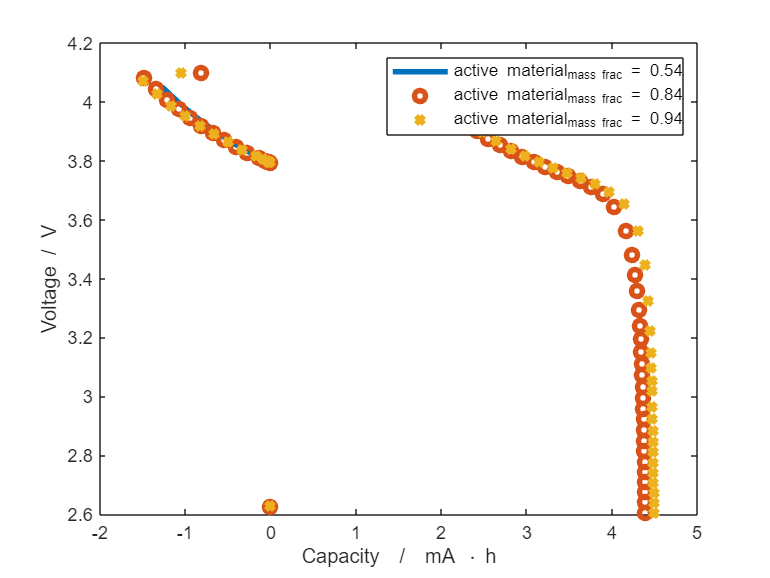

hold off
xlabel('Capacity  /  mA \cdot h')
ylabel('Voltage  /  V')
legend( 'active material_{mass frac} = 0.54', 'active material_{mass frac} = 0.84','active material_{mass frac} = 0.94')

Kinetic parameters:

Activation energy of reaction doesnt seem to do anything,

Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 330 Seconds
Solving timestep 16/45: 330 Seconds  -> 363 Seconds
Solving timestep 17/

*** Simulation complete. Solved 45 control steps in 2 Seconds, 622 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 676 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 536 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 630 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 658 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 535 Milliseconds ***


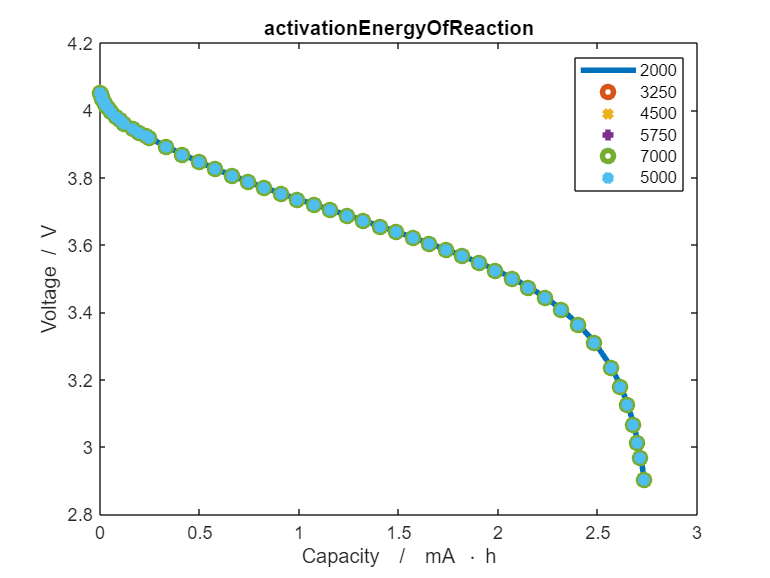

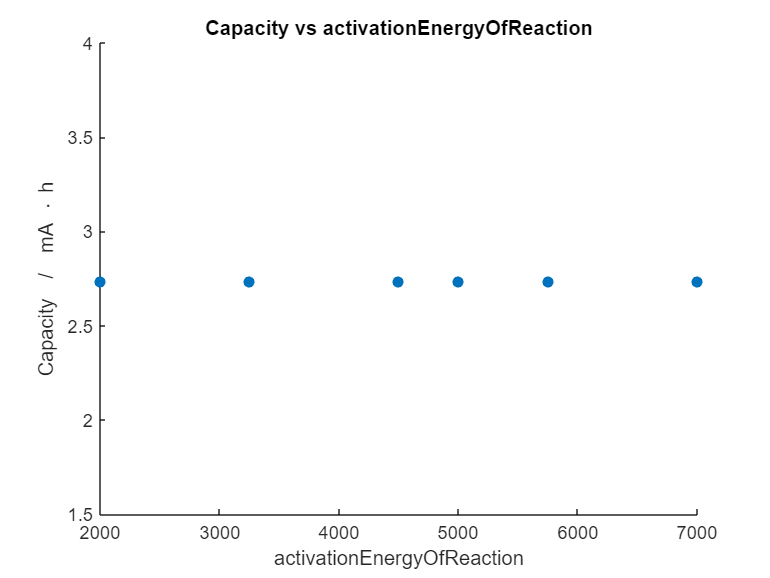

electrode_Ea="PositiveElectrode.";
crate_Ea=3;
kinetic_parameter_4=strcat(electrode_Ea,"Coating.ActiveMaterial.Interface.activationEnergyOfReaction");
kinetic_parameter_4_vals=[linspace(2000,7000,5),5000];
plot_capacities(kinetic_parameter_4_vals,kinetic_parameter_4,crate_Ea)

Charge transfer coefficient at the interface between electrode and electrolyte.

electrode_alpha="PositiveElectrode.";
crate_alpha=3;
kinetic_parameter_2_vals=[linspace(0.1,0.9,5),0.5];
kinetic_parameter_2=strcat(electrode_alpha,"Coating.ActiveMaterial.Interface.chargeTransferCoefficient");
plot_capacities(kinetic_parameter_2_vals,kinetic_parameter_2,crate_alpha), %crate to be set to 3

Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 330 Seconds
Solving timestep 16/45: 330 Seconds  -> 363 Seconds
Solving timestep 17/

*** Simulation complete. Solved 45 control steps in 3 Seconds, 103 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

Reaction rate constant- k

electrode_k="PositiveElectrode.";
crate_k=3;
kinetic_parameter_3=strcat(electrode_k,"Coating.ActiveMaterial.Interface.reactionRateConstant");
kinetic_parameter_3_vals=[linspace(5.031e-9,5.031e-12,5),5.031e-11];
plot_capacities(kinetic_parameter_3_vals,kinetic_parameter_3,crate_k)

Transference number $$t_+$$ 

crate_t=3;
kinetic_parameter_5="Electrolyte.species.transferenceNumber";
kinetic_parameter_5_vals=[linspace(0.3,0.4,5),0.25];
plot_capacities(kinetic_parameter_5_vals,kinetic_parameter_5,crate_t)

Transport properties

Active particle radius:

electrode_rad="PositiveElectrode.";
crate_radius=3;
transport_parameter_1=strcat(electrode_rad,"Coating.ActiveMaterial.SolidDiffusion.particleRadius");
transport_parameter_1_vals=[linspace(1,10,5)].*micro;
plot_capacities(transport_parameter_1_vals,transport_parameter_1,crate_radius)

Electronic conductivity of the electrodes

electrode_el_conductivity="NegativeElectrode.";
crate_el_conductivity=3;
transport_parameter_2=strcat(electrode_el_conductivity,"Coating.ActiveMaterial.electronicConductivity");
transport_parameter_2_vals=[linspace(0.5,1000,5),100];
plot_capacities(transport_parameter_2_vals,transport_parameter_2,crate_el_conductivity)

Electrolyte concentration-Diffusion 

Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 330 Seconds
Solving timestep 16/45: 330 Seconds  -> 363 Seconds
Solving timestep 17/

*** Simulation complete. Solved 45 control steps in 2 Seconds, 266 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 817 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 544 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 594 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

Solver failure after 6 iterations for timestep of length 16 Seconds, 500 Milliseconds. Cutting timestep.
Failure reason: Linear solver produced non-finite values.
Cutting timestep.
Solving timestep 36/45: 990 Seconds  -> 1023 Seconds
Solver did not converge in 10 iterations for timestep of length 2 Seconds, 375 Milliseconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 1 Second, 187 Milliseconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 593 Milliseconds. Cutting timestep.


*** Simulation complete. Solved 45 control steps in 2 Seconds, 676 Milliseconds ***
Solving timestep 01/45:              -> 1 Second, 31 Milliseconds
Solving timestep 02/45: 1 Second, 31 Milliseconds -> 2 Seconds, 62 Milliseconds
Solving timestep 03/45: 2 Seconds, 62 Milliseconds -> 4 Seconds, 125 Milliseconds
Solving timestep 04/45: 4 Seconds, 125 Milliseconds -> 8 Seconds, 250 Milliseconds
Solving timestep 05/45: 8 Seconds, 250 Milliseconds -> 16 Seconds, 500 Milliseconds
Solving timestep 06/45: 16 Seconds, 500 Milliseconds -> 33 Seconds
Solving timestep 07/45: 33 Seconds   -> 66 Seconds
Solving timestep 08/45: 66 Seconds   -> 99 Seconds
Solving timestep 09/45: 99 Seconds   -> 132 Seconds
Solving timestep 10/45: 132 Seconds  -> 165 Seconds
Solving timestep 11/45: 165 Seconds  -> 198 Seconds
Solving timestep 12/45: 198 Seconds  -> 231 Seconds
Solving timestep 13/45: 231 Seconds  -> 264 Seconds
Solving timestep 14/45: 264 Seconds  -> 297 Seconds
Solving timestep 15/45: 297 Seconds  -> 

Solver did not converge in 10 iterations for timestep of length 7 Seconds, 471 Milliseconds. Cutting timestep.


Solver did not converge in 10 iterations for timestep of length 3 Seconds, 735 Milliseconds. Cutting timestep.


Solver did not converge in 10 iterations for timestep of length 1 Second, 867 Milliseconds. Cutting timestep.


Solver did not converge in 10 iterations for timestep of length 1 Second, 334 Milliseconds. Cutting timestep.


Solver did not converge in 10 iterations for timestep of length 667 Milliseconds. Cutting timestep.


*** Simulation complete. Solved 45 control steps in 2 Seconds, 692 Milliseconds ***


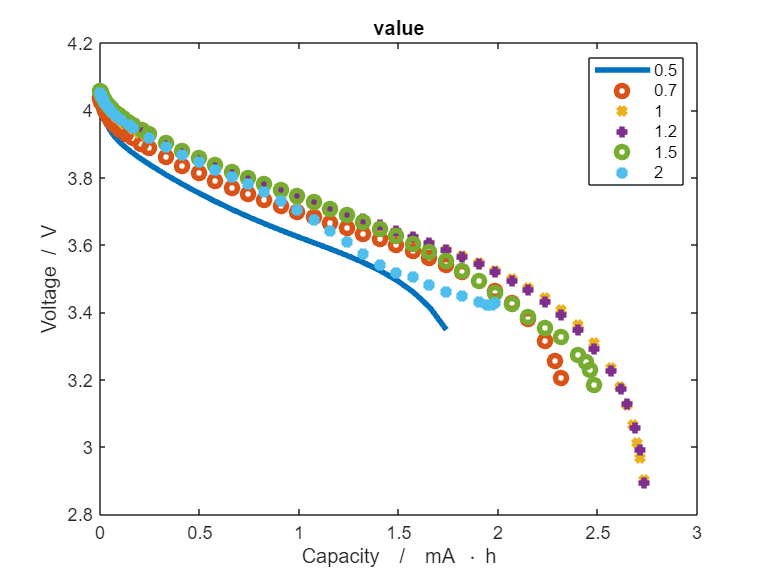

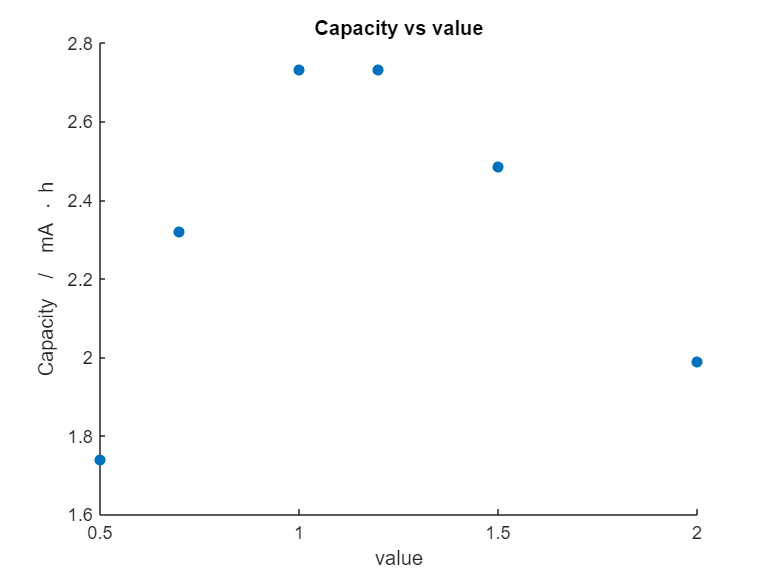

crate_el_conc=3;
transport_parameter_3_vals=[0.5,0.7,1.0,1.2,1.5,2];
transport_parameter_3="Electrolyte.initialConcentration.value";
plot_capacities(transport_parameter_3_vals,transport_parameter_3,crate_el_conc)

function plot_capacities(parameterArray1,input_parameter1,CRate)
    % Function to take in the specific input parameter along with its
    % values and c-rate and plot the capacities
    %
    % Parameters:
    % parameterArray - a numeric vector
    % input_parameter - a string specifying the operation ('sum', 'mean', 'scale')
    % crate - a numeric value used for scaling (only for 'scale' operation)
    %
    % Returns:
    % None
    % instantiate an empty figure
    capacity_array = [];
    output = cell(size(parameterArray1));
    figure()
    jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json'); % load default input
    if nargin == 3
        jsonstruct.Control.CRate = CRate;        
     end
    output = cell(size(parameterArray1));
    markers={'-',"o",'x','+','o','*','x','v','d','^','s','>','<'};
    for i = 1:numel(parameterArray1)
        C = split(input_parameter1,'.');
        jsonstruct = setfield(jsonstruct,C{:},parameterArray1(i));  
        jsonstruct.TimeStepping.totalTime = (1./jsonstruct.Control.CRate) .* 3600 .* 1.1;
        % run the simulation and store the results in the output cell array
        output{i} = runBatteryJson(jsonstruct);
         % retrieve the states from the simulation result
        states = output{i}.states;
        % extract the time and voltage quantities
        time = cellfun(@(state) state.time, states);
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % calculate the capacity
        capacity = time .* current;
        final_capacity=capacity(find(capacity, 1, 'last'))/(hour*milli);
        capacity_array(i)=final_capacity;
        % plot capacity vs voltage
        plot((capacity/(hour*milli)), voltage, markers{i}, 'linewidth', 3);
        xlabel('Capacity  /  mA \cdot h')
        ylabel('Voltage  /  V')
        hold on
        L{i} = strcat(num2str(parameterArray1(i)));
        legend(L);
        title(C{end})
    end
    figure;
    scatter(parameterArray1,capacity_array,"filled")
    ylabel('Capacity  /  mA \cdot h')
    xlabel(C{end})
    title(strcat("Capacity vs ",C{end}));
end


